# **Coin Counting Project**

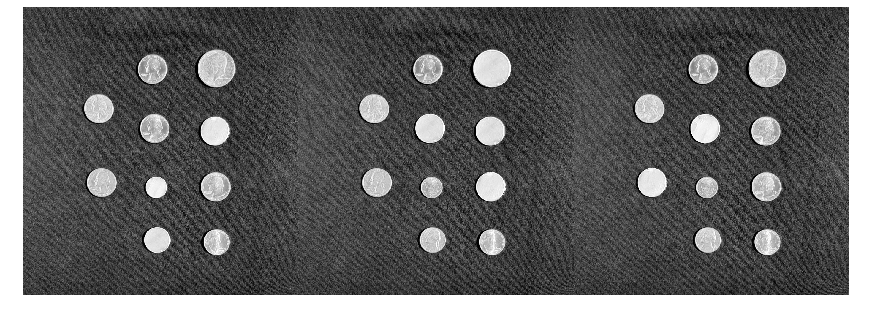

coinImages = {"testCoinImage1.png","testCoinImage2.png","testCoinImage3.png"};
montage(coinImages,"Size",[1,3])

## Segmenting Foreground

BW = cell(1, numel(coinImages));
maskedImages = cell(1, numel(coinImages));

for k = 1:numel(coinImages)
    coinImg = imread(coinImages{k});
    filteredCoinImg = imgaussfilt(coinImg);
    [BW{k}, maskedImages{k}] = segmentCoins(filteredCoinImg);
end

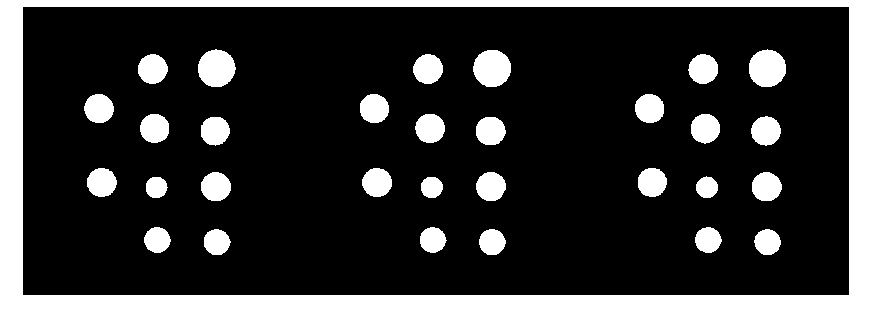

montage(BW,"Size",[1,3])

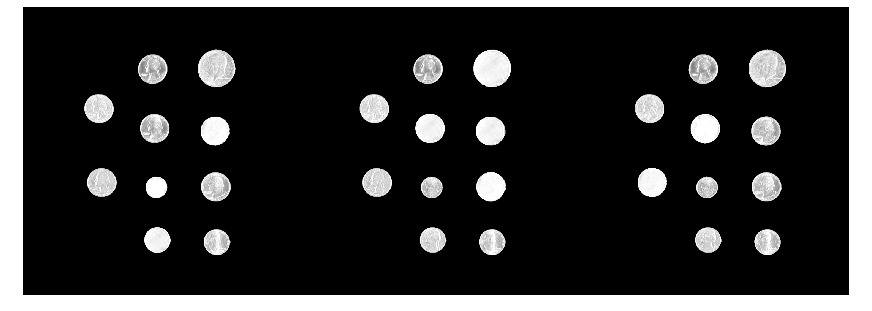

montage(maskedImages,"Size",[1,3])

## Isolating Coin Face Edges

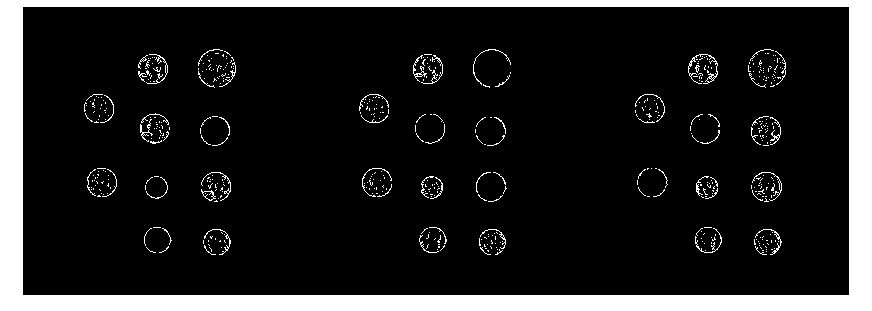

coinImgEdges = cell(1, numel(maskedImages));
erodedMasks = cell(1, numel(maskedImages));
faceEdgeMask = cell(1, numel(maskedImages));
expandedEdgeMasks = cell(1, numel(maskedImages));
for j = 1:numel(maskedImages)
    coinImgEdges{j} = edge(maskedImages{j}, "sobel", "nothinning");
    erodedMasks{j} = imerode(maskedImages{j}, strel('disk', 16));
    faceEdgeMask{j} = coinImgEdges{j} & erodedMasks{j};
    expandedEdgeMasks{j} = imdilate(faceEdgeMask{j}, strel('disk', 28));
end
montage(coinImgEdges, "Size", [1,3]);

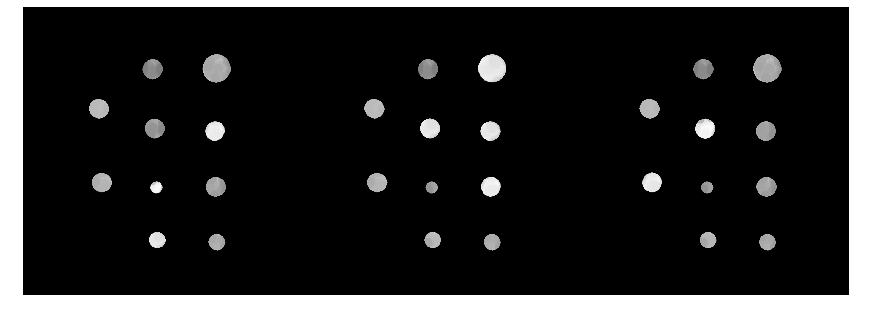

montage(erodedMasks, "Size", [1,3]);

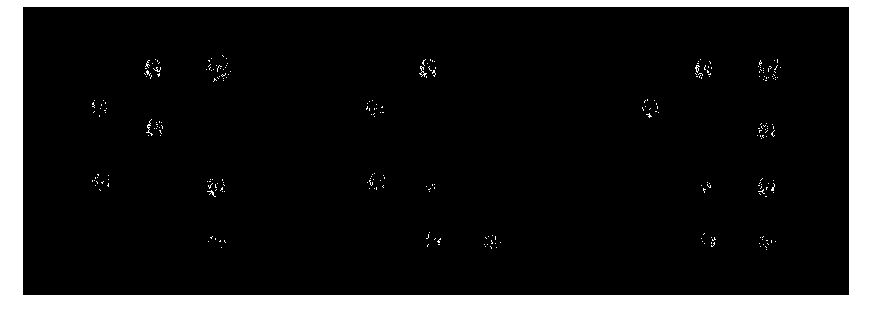

montage(faceEdgeMask, "Size", [1,3]);

## Creating a Valid Coin Mask

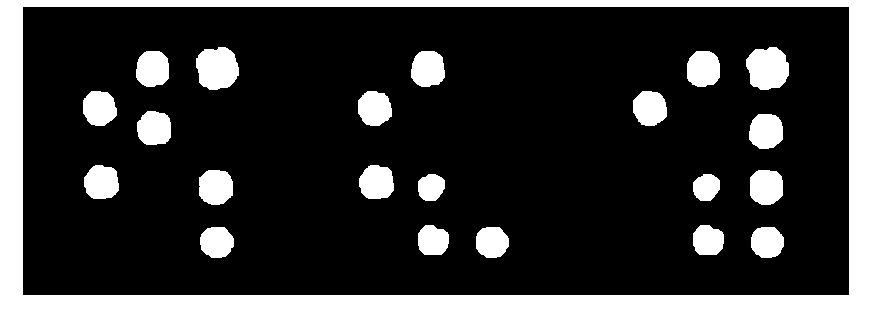

montage(expandedEdgeMasks, "Size", [1,3]);

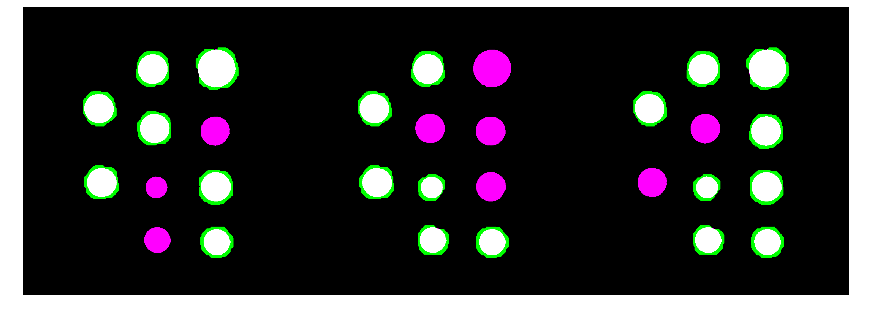

fusedPairs = cell(1, numel(expandedEdgeMasks));
for i = 1:numel(expandedEdgeMasks)
    fusedPairs{i} = imfuse(expandedEdgeMasks{i}, BW{i});
end
montage(fusedPairs, "Size", [1,3]);

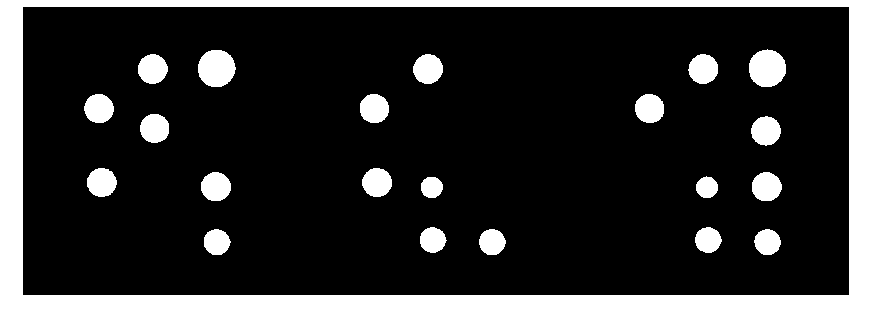

validRegions = cell(1, numel(expandedEdgeMasks));
nDimes = cell(1, numel(expandedEdgeMasks));
nNickels = cell(1, numel(expandedEdgeMasks));
nQuarters = cell(1, numel(expandedEdgeMasks));
nFiftyCents = cell(1, numel(expandedEdgeMasks));
USD = cell(1, numel(expandedEdgeMasks));
for i = 1:numel(expandedEdgeMasks)
    validRegions{i} = expandedEdgeMasks{i} & BW{i};
    nDimes{i} = bwpropfilt(validRegions{i}, 'Area',[4000, 5000]);
    nDimes{i} = length(regionprops(nDimes{i}));
    nNickels{i} = bwpropfilt(validRegions{i}, 'Area',[5000, 7000]);
    nNickels{i} = length(regionprops(nNickels{i}));
    nQuarters{i} = bwpropfilt(validRegions{i}, 'Area',[7000, 9000]);
    nQuarters{i} = length(regionprops(nQuarters{i}));
    nFiftyCents{i} = bwpropfilt(validRegions{i}, 'Area',[10000, 13000]);
    nFiftyCents{i} = length(regionprops(nFiftyCents{i}));
    USD{i} = nDimes{i}*0.10 + nNickels{i}*0.05 + nQuarters{i}*0.25 + nFiftyCents{i}*0.50;
end
montage(validRegions, "Size", [1,3]);

## Counting Valid Coins

nDimes, nNickels, nQuarters, nFiftyCents, USD

nDimes = 1×3 cell array
    {[0]}    {[1]}    {[1]}


nNickels = 1×3 cell array
    {[1]}    {[2]}    {[2]}


nQuarters = 1×3 cell array
    {[5]}    {[3]}    {[4]}


nFiftyCents = 1×3 cell array
    {[1]}    {[0]}    {[1]}


USD = 1×3 cell array
    {[1.8000]}    {[0.9500]}    {[1.7000]}
